# Illustrative Example: Bounds on Inverses

## Initialization

clear;
epsl = 1e-5;
% Colorblind-safe color palette (Wong, B. Points of view: Color blindness.
% Nat Methods 8,441 (2011). https://doi.org/10.1038/nmeth.1618)
color.black = [0 0 0]/255;
color.orange = [230 159 0]/255;
color.cyan = [86 180 233]/255;
color.green = [0 158 115]/255;
color.yellow = [240 228 66]/255;
color.blue = [0 114 178]/255;
color.red = [213 94 0]/255;
color.pink = [204 121 167]/255;


## Example

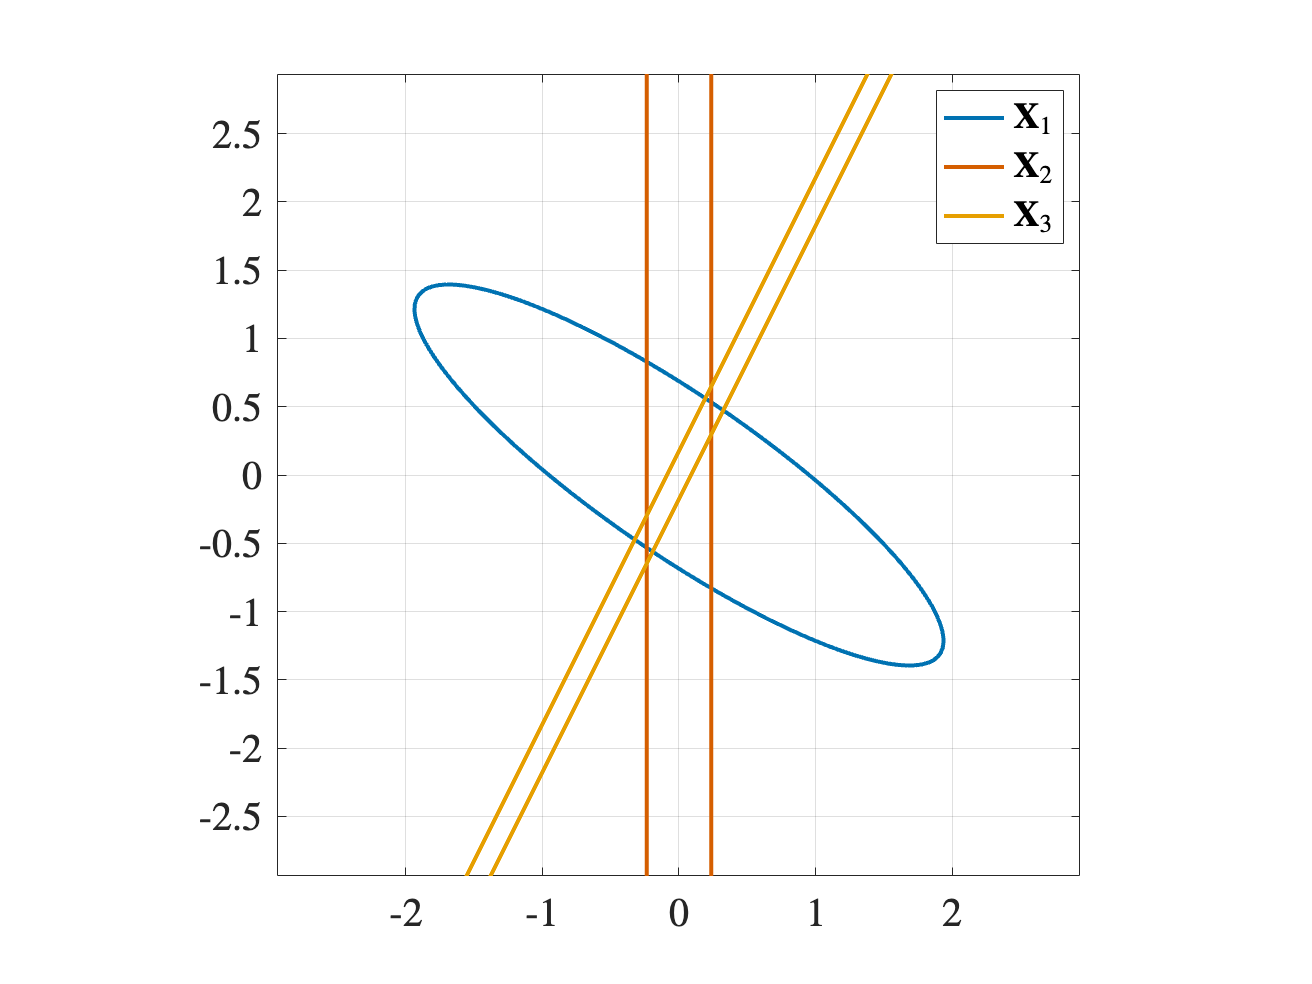

% Scenario selection
% Seeds:
% 8: is quite aesthetic
rng(23);
M = 3;
Xb = cell(M,1);
Wb = cell(M,1);
Yb = cell(M,1);

% 1. Normal bound (X<= Xb1)
Xb{1,1} = 2*(rand(2,2)-0.5);
Xb{1,1} = Xb{1,1}*Xb{1,1}';
% In this case it is the same as Y1 = inv(X1)
Wb{1,1} = 2*(rand(2,2)-0.5); %eye(2);
%Wb{1,1} = eye(2);
%Yb{1,1} = invertBound(Wb{1,1},inv(Xb{1,1})); 
Yb{1,1} = (Wb{1,1}'/Xb{1,1})*Wb{1,1};

% 2. Bound on an principal component (X_11 <= Xb2_11)
Wb{2,1} = [1 0];
Xb{2,1} = 2*(rand(1,1)-0.5);
Xb{2,1} = Xb{2,1}*Xb{2,1}';
% Equivalent of
% X2 = [1 0;
%       0 +inf]
%Yb{2,1} = invertBound(Wb{2,1},inv(Xb{2,1}));
Yb{2,1} = (Wb{2,1}'/Xb{2,1})*Wb{2,1};

% 3. Bound on an nonprincipal component (X_11 <= Xb2_11)
Wb{3,1} = [2 -1];
Xb{3,1} = 2*(rand(1,1)-0.5);
Xb{3,1} = Xb{3,1}*Xb{3,1}';
%Yb{3,1} = invertBound(Wb{3,1},inv(Xb{3,1}));
Yb{3,1} = (Wb{3,1}'/Xb{3,1})*Wb{3,1};


% Plot elipsoids
elpsXb1 = plotCov(Yb{1,1});
elpsXb2 = plotCov(Yb{2,1}+epsl*eye(2));
elpsXb3 = plotCov(Yb{3,1}+epsl*eye(2));
figure('Position',4*[0 0 192 144]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca,'TickLabelInterpreter','latex') % Latex style axis
plot(elpsXb1(1,:),elpsXb1(2,:),'LineWidth',2,'Color',color.blue);
plot(elpsXb2(1,:),elpsXb2(2,:),'LineWidth',2,'Color',color.red);
plot(elpsXb3(1,:),elpsXb3(2,:),'LineWidth',2,'Color',color.orange);
legend({'$\mathbf{X}_1$','$\mathbf{X}_2$','$\mathbf{X}_3$'},'Interpreter','latex')
axis equal;
lim_axis = max([max(elpsXb1(1,:)) max(elpsXb1(2,:))])+1;
xlim(lim_axis*[-1 1]);
ylim(lim_axis*[-1 1]);

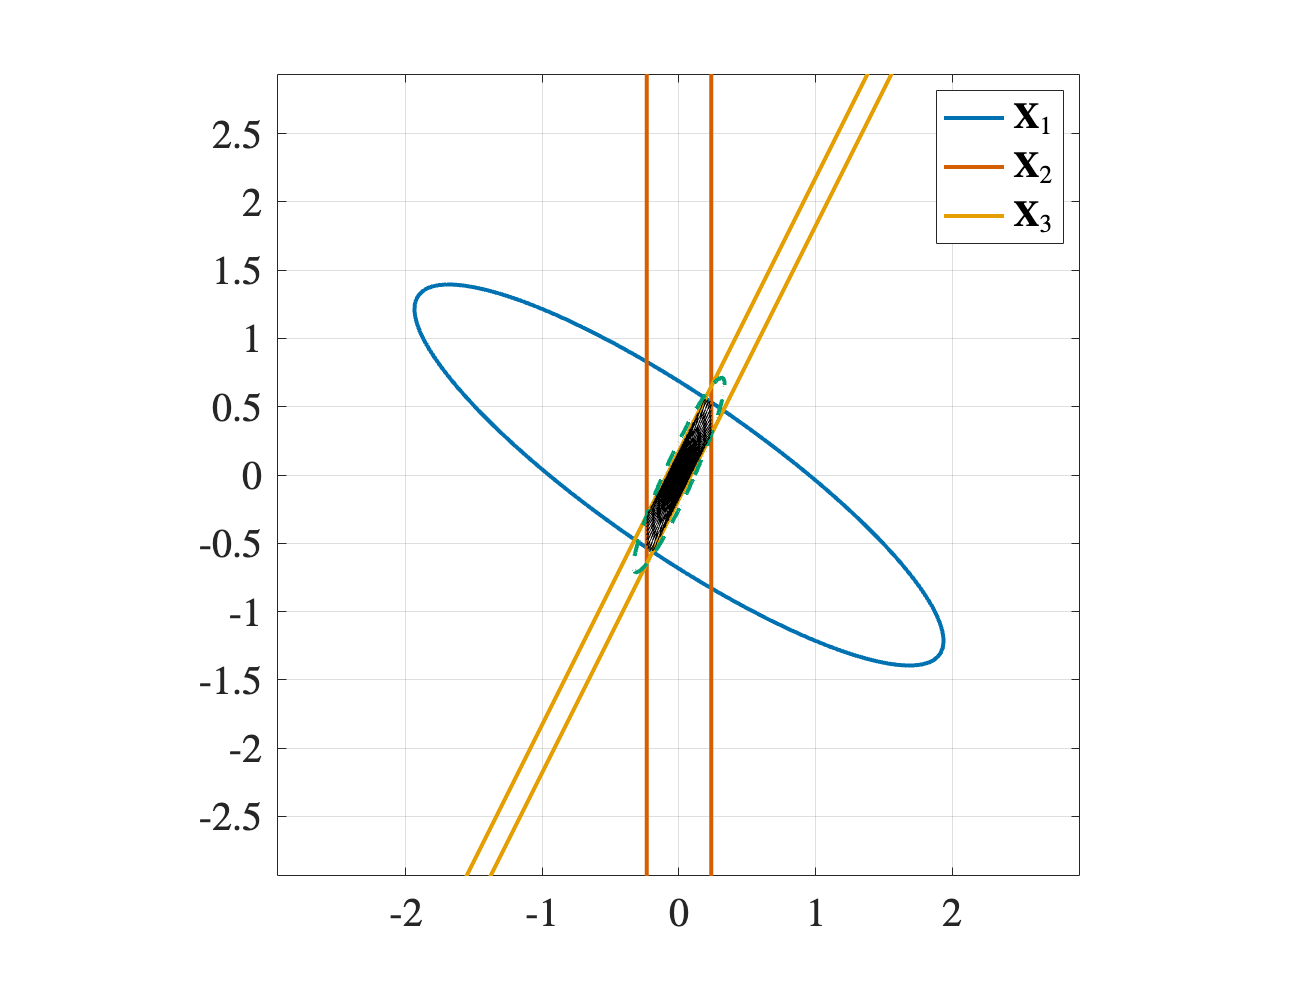


omega = rand(M,1);
omega = omega/sum(omega);
Binv = zeros(2,2);
for i = 1:M
    Binv = Binv + omega(i)*Yb{i,1};
end
elpsB = plotCov(Binv);
figure('Position',4*[0 0 192 144]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca,'TickLabelInterpreter','latex') % Latex style axis
plot(elpsXb1(1,:),elpsXb1(2,:),'LineWidth',2,'Color',color.blue);
plot(elpsXb2(1,:),elpsXb2(2,:),'LineWidth',2,'Color',color.red);
plot(elpsXb3(1,:),elpsXb3(2,:),'LineWidth',2,'Color',color.orange);
plot(elpsB(1,:),elpsB(2,:),'LineWidth',2,'Color',color.green,'LineStyle','--');
axis equal;
% Plot admissible covariances
EgElepsoidsN = 1e2;
EgElepsoidsEcc = 1e-3;
opts = optimset('Display','off');
theta = 0:(pi/(EgElepsoidsN-1)):pi;
for j = 1:EgElepsoidsN
    S = [cos(theta(j)) -sin(theta(j)); sin(theta(j)) cos(theta(j))];
    P = S*diag([1 EgElepsoidsEcc])*S';
    tmax = zeros(M,1);
    for i = 1:M
        fun = @(t) min(eig(Xb{i,1}-t*Wb{i,1}*P*Wb{i,1}'));
        tmax(i) = fsolve(fun,1e-3,opts);
    end
    P = min(tmax)*P;
    %min(eig(Xb{1,1}-Wb{1,1}*P*Wb{1,1}'))
    elpsP = plotCov(inv(P));
    plot(elpsP(1,:),elpsP(2,:),'LineWidth',0.5,'Color',color.black,'HandleVisibility','off');
    if max(elpsP(2,:))> 0.6
        Pdebug = P;
    end
end
lim_axis = max([max(elpsXb1(1,:)) max(elpsXb1(2,:))])+1;
xlim(lim_axis*[-1 1]);
ylim(lim_axis*[-1 1]);
legend({'$\mathbf{X}_1$','$\mathbf{X}_2$','$\mathbf{X}_3$'},'Interpreter','latex');

## Debug

% Pdebug
% 
% % Does it satisfy Xb{i,1} >= Wb{i,1}*P*Wb{i,1}'? Yes
% min(eig(Xb{1,1}-Wb{1,1}*P*Wb{1,1}'))
% 
% % Does it satisfy P^-1 >= Yb? No
% min(eig(P-Yb{1,1}))
% 
% % Does it satisfy 
% invertBound(Wb{1,1},inv(Xb{1,1})); 

## Bounds after Affine Transformation

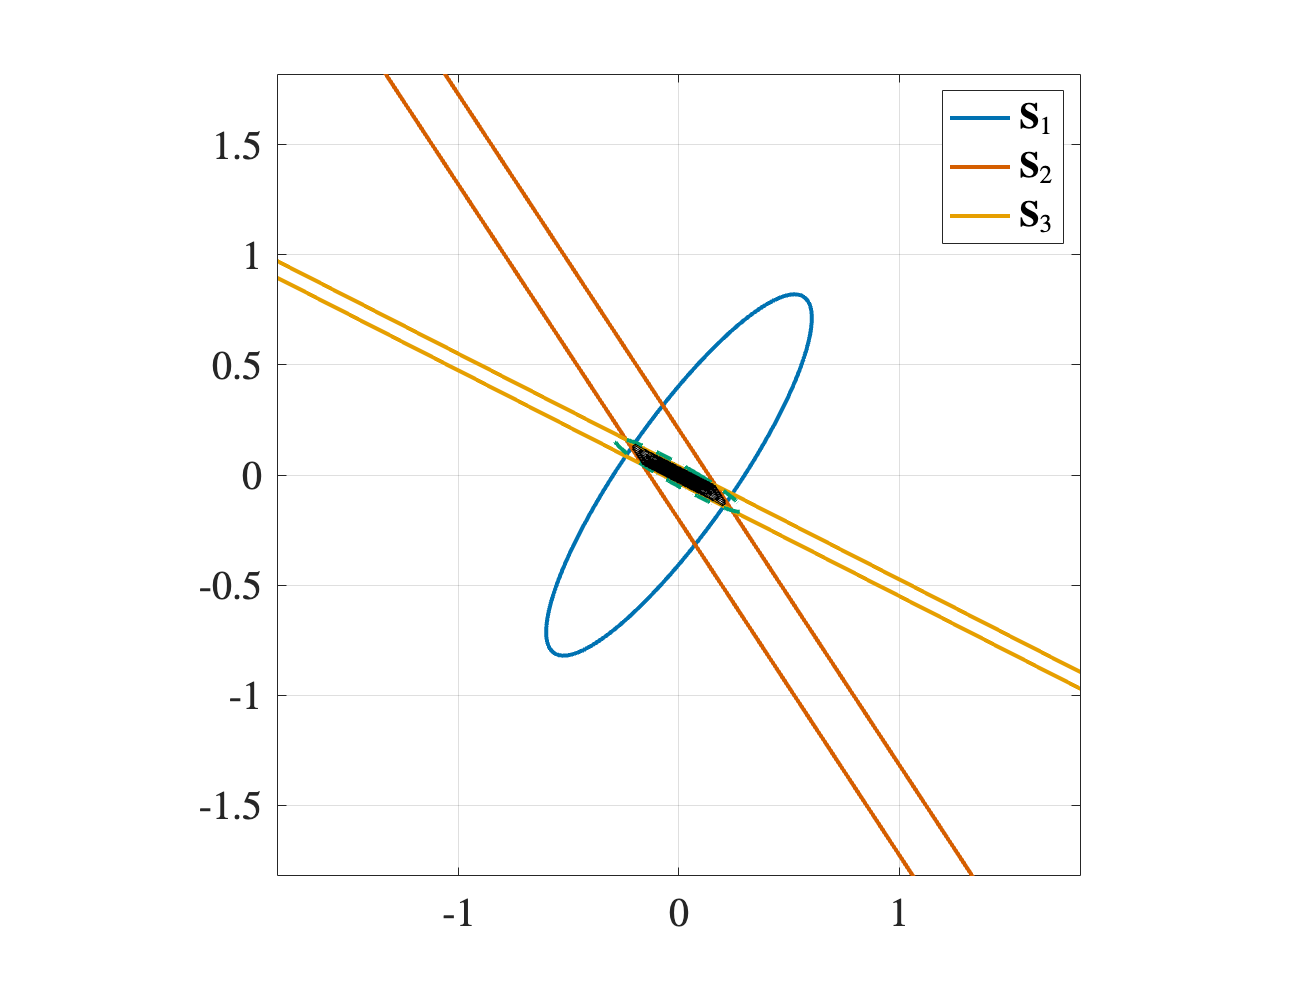

% What if now we have 
% P = R * C*E*C'
% WEW' <= X_i, i = 1,...,M
% Now we finds bounds S_i
% P^-1 >= S_i

% Generate R and C
R = 2*(rand(2,2)-0.5);
R = epsl*R*R';
C = (rand(2,2)-0.5);
%C = eye(2);
Sb = cell(M,1);
for i = 1:M
    Sb{i,1} = inv(R)-((R\C)/(Yb{i,1}+(C'/R)*C))*(C'/R);
end
SB = inv(R)-((R\C)/(Binv+(C'/R)*C))*(C'/R);

elpsSb1 = plotCov(Sb{1,1});
elpsSb2 = plotCov(Sb{2,1}+epsl*eye(2));
elpsSb3 = plotCov(Sb{3,1}+epsl*eye(2));
elpsSB = plotCov(SB);
figure('Position',4*[0 0 192 144]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca,'TickLabelInterpreter','latex') % Latex style axis
plot(elpsSb1(1,:),elpsSb1(2,:),'LineWidth',2,'Color',color.blue);
plot(elpsSb2(1,:),elpsSb2(2,:),'LineWidth',2,'Color',color.red);
plot(elpsSb3(1,:),elpsSb3(2,:),'LineWidth',2,'Color',color.orange);
plot(elpsSB(1,:),elpsSB(2,:),'LineWidth',2,'Color',color.green,'LineStyle','--');
axis equal;
% Plot admissible covariances
for j = 1:EgElepsoidsN
    S = [cos(theta(j)) -sin(theta(j)); sin(theta(j)) cos(theta(j))];
    P = S*diag([1 EgElepsoidsEcc])*S';
    tmax = zeros(M,1);
    for i = 1:M
        fun = @(t) min(eig(Xb{i,1}-t*Wb{i,1}*P*Wb{i,1}'));
        tmax(i) = fsolve(fun,1e-3,opts);
    end
    P = min(tmax)*P;
    elpsP = plotCov(inv(R+C*P*C'));
    plot(elpsP(1,:),elpsP(2,:),'LineWidth',0.5,'Color',color.black,'HandleVisibility','off');
end
lim_axis = max([max(elpsSb1(1,:)) max(elpsSb1(2,:))])+1;
xlim(lim_axis*[-1 1]);
ylim(lim_axis*[-1 1]);
legend({'$\mathbf{S}_1$','$\mathbf{S}_2$','$\mathbf{S}_3$'},'Interpreter','latex');


return;

## Trash

## What is happening

eg = load('invertBound_eg.mat');
Yb = invertBound(eg.Weg,inv(eg.Xeg));

% Plot elipsoids
elpsXb = plotCov(inv(eg.Xeg));
elpsYb = plotCov(Yb);
elpsP = plotCov(inv(eg.Peg));
figure('Position',4*[0 0 192 144]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca,'TickLabelInterpreter','latex') % Latex style axis
plot(elpsXb(1,:),elpsXb(2,:),'LineWidth',2,'Color',color.blue);
plot(elpsYb(1,:),elpsYb(2,:),'LineWidth',2,'Color',color.red);
plot(elpsP(1,:),elpsP(2,:),'LineWidth',2,'Color',color.green);
legend({'$\mathbf{X}$','$\mathbf{X}$'},'Interpreter','latex')
axis equal;
lim_axis = max([max(elpsXb(1,:)) max(elpsXb(2,:))])+1;
xlim(lim_axis*[-1 1]);
ylim(lim_axis*[-1 1]);

eig(inv(eg.Peg)-Yb)'

